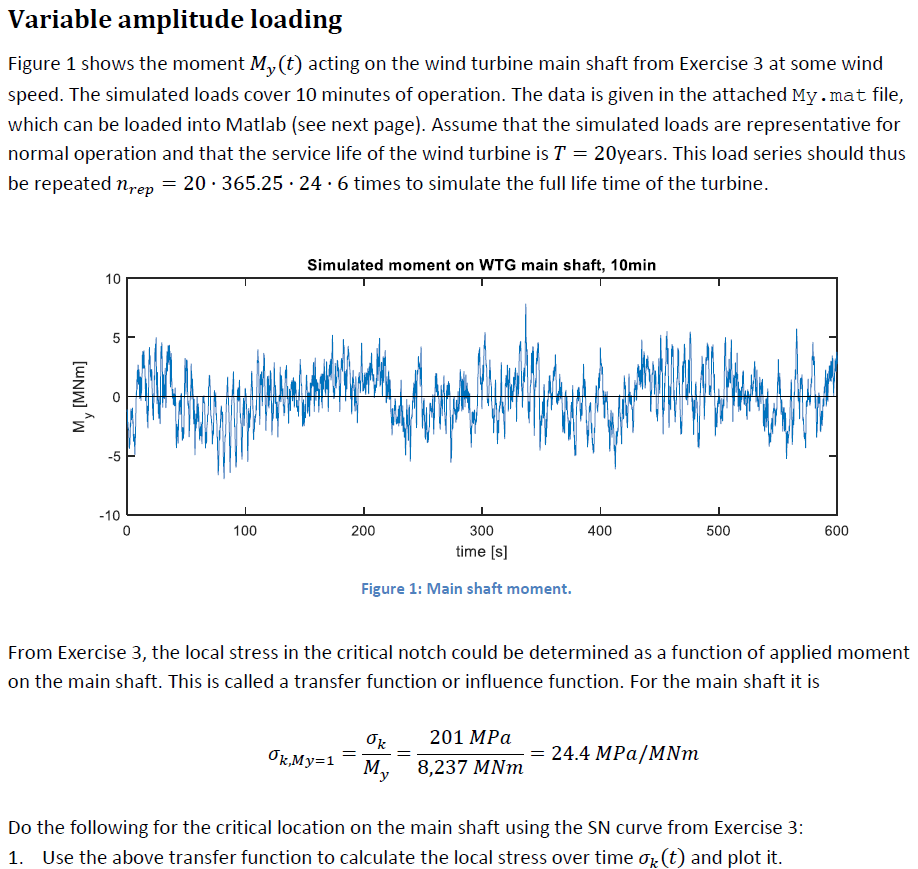

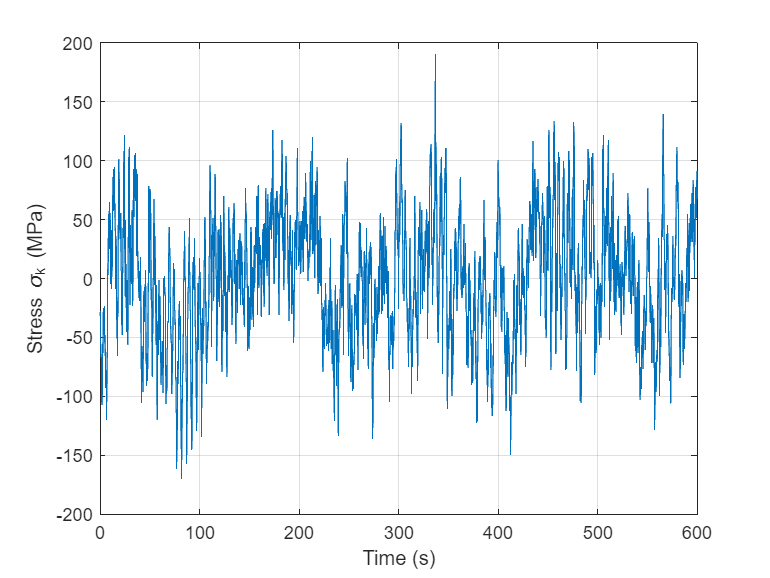

clear all
clf
format longg
load My.mat
% My [MPa]
% t [s]

S_k_my1 = 24.4; % MPa / MNm

S_k = S_k_my1*My;

plot(t,S_k)%, "filled")
xlabel('Time (s)')
ylabel('Stress \sigma_k (MPa)')
grid("on")

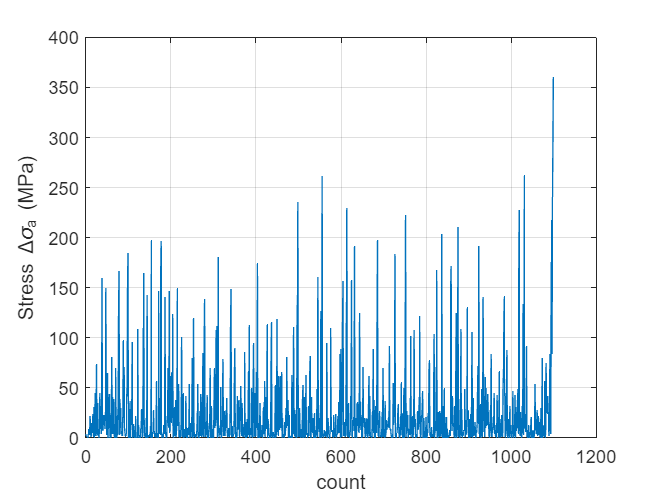

[dS, Sm] = rainflow(S_k); %[dS,Sm] = rainflow(S)
% dS % is the stress range
% Sm % is the associated mean stresses

t_a = linspace(0, length(dS), length(dS));
plot(t_a,dS)%, "filled")
xlabel('count')
ylabel('Stress \Delta\sigma_a (MPa)')
grid("on")

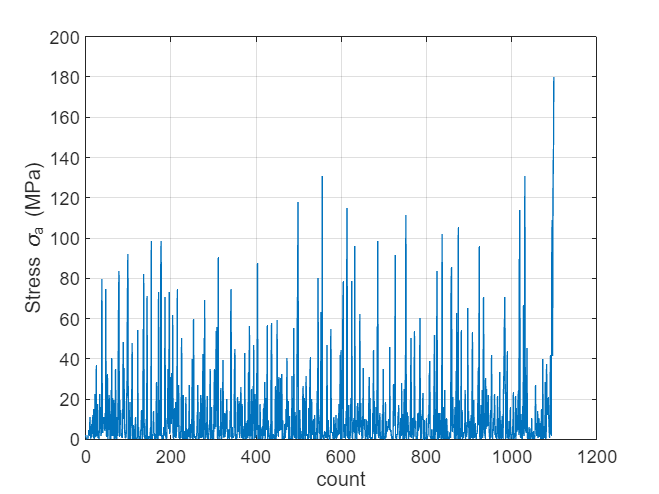

S_a = dS/2;
S_RDk_safe_97 = 153.2027; % fra opgave 3 97.7% med sikkerheds factor y_Mf = 1.265;
t_a = linspace(0, length(S_a), length(S_a));
plot(t_a,S_a)%, "filled")
xlabel('count')
ylabel('Stress \sigma_a (MPa)')
grid("on")

S_a_max = max(S_a)

S_a_max =                 180.158925


Vi deler først dataen op så det der er før knæet bliver fundet med m1 og det efter findes med m2

Jeg plotter dataen for at se hvordan det passer

N_D = 1e6;
m1 = 5;
m2 = 2*m1 - 1

m2 =      9



C1 = S_RDk_safe_97^m1 * N_D

C1 =       8.43979885451075e+16


C2 = S_RDk_safe_97^m2 * N_D

C2 =        4.6494092274223e+25



N_a1 = [];
N_a2 = [];
S_a1 = [];
S_a2 = [];
N_max = 1e12

N_max =              1000000000000


for i = 1:length(S_a)
    if S_a(i) > S_RDk_safe_97
        N_a1(end +1) = C1 / S_a(i)^m1; %finder et punkt for S_1 med vores maximale lokal spænding
        S_a1(end +1) = S_a(i);
    else
    N_a2_check = C2 / S_a(i)^m2;
        % if  N_a2_check > N_max
            % continue
        % else
            N_a2(end +1) = N_a2_check; %finder et punkt for S_1 med vores maximale lokal spænding
            S_a2(end +1) = S_a(i);
        % end
    end
end
length(N_a1)

ans =      1


length(N_a2)

ans =         1098


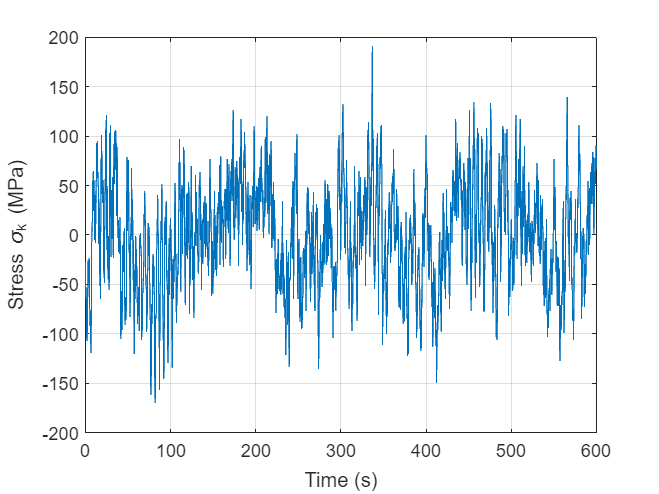

% scatter(N_a1,S_a1)%, "filled")
loglog(N_a1,S_a1, 'o')%, "filled")
hold on
% scatter(N_a2,S_a2)%, "filled")
loglog(N_a2,S_a2, 'o')%, "filled")
xlabel('Cycles')
ylabel('Stress \sigma_a (MPa)')
grid("on")
hold off

**Finder damage**

year20 = 20 * 365.25 *24 * 6 % 10 minutters tid serien ganges op til 20 år

year20 =      1051920



for i = 1:length(N_a1)
    Ds1(i) = year20/N_a1(i); % Palmgren-Miner
end

for i = 1:length(N_a2)
    Ds2(i) = year20/N_a2(i); % Palmgren-Miner
end
D_20year = sum(Ds1) + sum(Ds2)

D_20year =           4.23718605979565




for i = 1:length(N_a1)
    Ds1(i) = 1/N_a1(i); % Palmgren-Miner
end

for i = 1:length(N_a2)
    Ds2(i) = 1/N_a2(i); % Palmgren-Miner
end

D_10min = sum(Ds1) + sum(Ds2)

D_10min =       4.02804971841551e-06



D_20year = year20 * D_10min

D_20year =           4.23718605979565


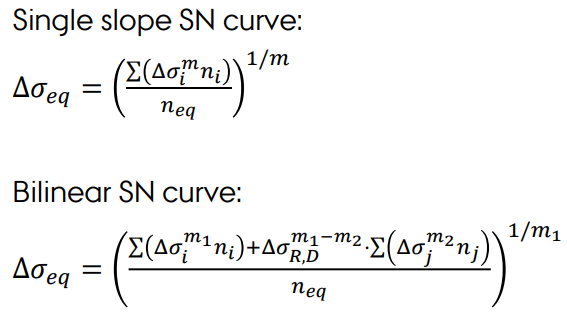

n_i = year20;
n_j = year20;
n_eq = N_D % year20 %

n_eq =      1000000



n_applied = length(S_a) * year20

n_applied =                 1156060080



S_a_eq =  ((sum(S_a1.^m1 .* n_i) + S_RDk_safe_97^(m1-m2) * sum(S_a2.^m2 .* n_j) ) /...
        n_eq)^(1/m1)

S_a_eq =           204.494638580253


N_est = n_applied/D_20year;
fprintf('n_applied = %10i\n',n_applied)

n_applied = 1156060080


fprintf('Nest =      %10i cycles\n',round(N_est))

Nest =       272836751 cycles


fprintf('Nest = %10f years\n',20/D_20year)

Nest =   4.720114 years


UR = S_a_eq/((mean(S_a1) + mean(S_a2))/2)

UR =           2.12716257463991


Rm = 400; %MPa 
k_mean = (1-mean(Sm)/Rm)

k_mean =          0.997607206139104


S_RDk_safe_97

S_RDk_safe_97 =                   153.2027


S_RDk_safe_97_k_mean = S_RDk_safe_97 * k_mean

S_RDk_safe_97_k_mean =           152.836117519967
